%RBE501_HW2_2a
%Ali Abdelhamid
clear all
clc

## POE FWD KIN

%M and Slist derrived from robot in home position (all thetas = 0):

syms th1 th2

M = [1,0,0,600;
    0,1,0,0;
    0,0,1,0;
    0,0,0,1];

Slist = [[0;0;1;0;0;0],[0;0;1;0;-300;0]];

thetalist = [th1; th2];

%Iterative loop for deriving array of ES matrixes 
I = eye(3);  %identity matrix
T = {};      %define T as an array to store all ES matrixes

for i = 1 : length(thetalist)
    w = skew(Slist(1:3,i));
    v = Slist(4:6,i);
    theta = thetalist(i);
    
    R = I + sin(theta)*w + (1-cos(theta))*w^2;
    
    star = (I*theta + (1-cos(theta))*w + (theta-sin(theta))*w^2)*v;
    
    T{i} = [R star; 0 0 0 1];
end

T = T{1}*T{2}*M;

## CALCULATING JACOBIAN

p = T(1:3,4);

Jv = jacobian(p,[th1,th2]);

## Solver for 3 degree polynomial coefficients (4 unkowns)

%Note that a0 and a1 were already derived on paper
% syms a0 a1 a2 a3
% 
% ti = 0;
% tf = 5;
% 
% 
% eqn1 = a0 +a1*ti + a2*ti^2 + a3*ti^3 == 0.8957;
% eqn1_dot = a1 + 2*a2*ti + 3*a3*ti^2 == 0;
% eqn2 = a0 +a1*tf + a2*tf^2 + a3*tf^3 == 0.8957;
% eqn2_dot = a1 + 2*a2*tf + 3*a3*tf^2 == 0;
% 
% [s_a0, s_a1, s_a2, s_a3] = solve([eqn1, eqn1_dot, eqn2, eqn2_dot], [a0, a1, a2, a3]);

## Plotting Trajectory Equations [JOINT SPACE]

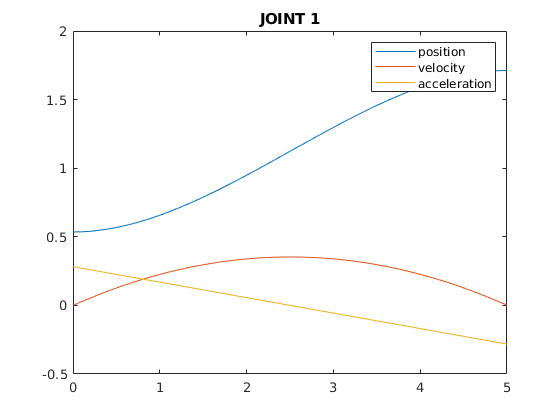

%plugged in ploynomial coefficients
syms t

%joint 1
eq1 = 0.5350 + 0.1411*(t)^2 - 0.0188*(t)^3;
eq1_d = 2*(0.1411)*(t) - 3*(0.0188)*(t)^2;
eq1_dd = 2*0.1411 - 6*(0.0188)*(t);
%joint 2
eq2 = 0.8957;
eq2_d = 0;
eq2_dd = 0;

%for joint 1
x = 0:0.1:5;
eq1_set = subs(eq1, t, x);
figure (1)
plot(x,eq1_set)
hold on
eq1_d_set = subs(eq1_d, t, x);
plot(x,eq1_d_set)
hold on
eq1_dd_set = subs(eq1_dd, t, x);
plot(x,eq1_dd_set)
title('JOINT 1')
legend({'position', 'velocity', 'acceleration'})

## for joint 2

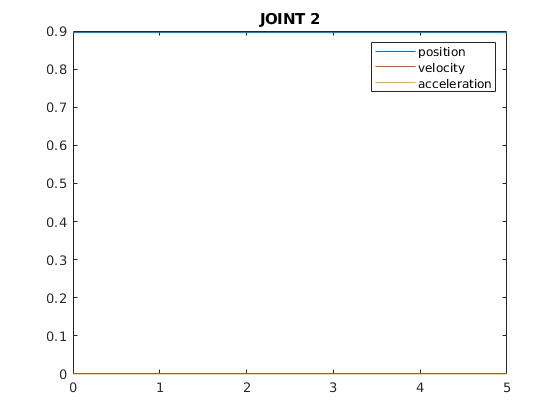

x = 0:0.1:5;
eq2_set = subs(eq2, t, x);
figure (2)
plot(x,eq2_set)
hold on
eq2_d_set = subs(eq2_d, t, x);
plot(x,eq2_d_set)
hold on
eq2_dd_set = subs(eq2_dd, t, x);
plot(x,eq2_dd_set)
hold on
title('JOINT 2')
legend({'position', 'velocity', 'acceleration'})

## Plotting EE [TASK SPACE] NOT trajectory planning, just plotting

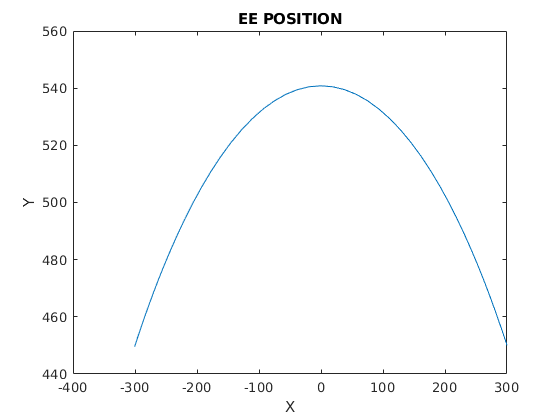

%Note how we grab the data sets from the previous plots
%since the trajectory for the joints is already predifined

%position
syms th1 th2
%plugging in range of q values from previous plot
%I am struggling with subbing 2 variables with 2 vectors so I split it
position_x_set_1 = subs(p(1), th1, double(eq1_set)); 
position_x_set = subs(position_x_set_1, th2, 0.8957);
position_y_set_1 = subs(p(2), th1, double(eq1_set));
position_y_set = subs(position_y_set_1, th2, 0.8957);

figure (3)
plot(position_x_set, position_y_set)
hold on
title ('EE POSITION')
xlabel('X')
ylabel('Y')

## Velocity

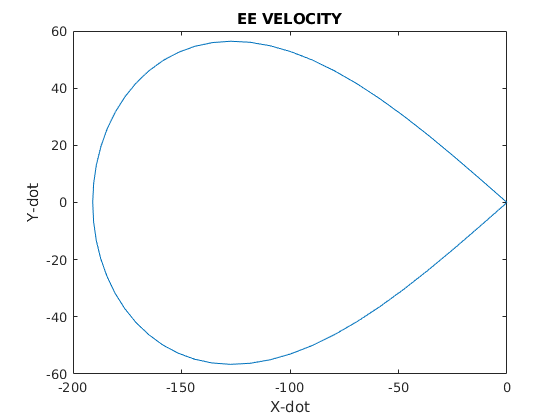

%populating the Jacobian over time
Jv_x1 = subs(Jv(1,1), th1, double(eq1_set));
Jv_x11 = subs(Jv_x1, th2, 0.8957);
Jv_x2 = subs(Jv(1,2), th1, double(eq1_set));
Jv_x22 = subs(Jv_x2, th2, 0.8957);

x_velocity = (double(Jv_x11).*double(eq1_d_set)) + (double(Jv_x22).*double(eq2_d_set));

Jv_y1 = subs(Jv(2,1), th1, double(eq1_set));
Jv_y11 = subs(Jv_y1, th2, 0.8957);
Jv_y2 = subs(Jv(2,2), th1, double(eq1_set));
Jv_y22 = subs(Jv_y2, th2, 0.8957);

y_velocity = (double(Jv_y11).*double(eq1_d_set)) + (double(Jv_y22).*double(eq2_d_set));

figure (4)
plot(x_velocity,y_velocity)
hold on
title('EE VELOCITY')
xlabel('X-dot')
ylabel('Y-dot')

## Acceleration

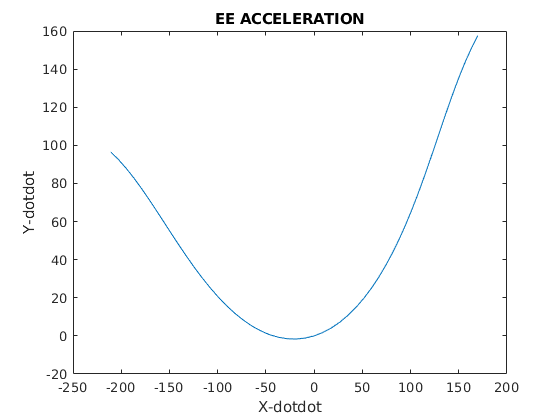


%Here we can use the same Jv_x and Jv_y from the velocity section since
%the Jacobian is defined by the joint values which are predefined by
%their trajectory So we just multiply Jv columns by q dot dot:
x_acceleration = (double(Jv_x11).*double(eq1_dd_set)) + (double(Jv_x22).*double(eq1_dd_set));
y_acceleration = (double(Jv_y11).*double(eq1_dd_set)) + (double(Jv_y22).*double(eq1_dd_set));

figure (5)
plot(x_acceleration,y_acceleration)
hold on
title('EE ACCELERATION')
xlabel('X-dotdot')
ylabel('Y-dotdot')

## Functions

function skewMatrix = skew(a)
        skewMatrix = [0,-a(3),a(2);
        a(3),0,-a(1);
        -a(2),a(1),0];
end